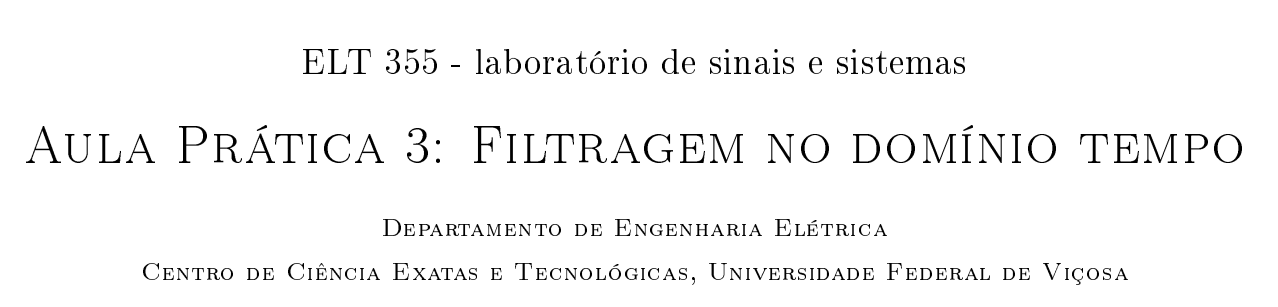

19/05/22

**Aluno:** Déric A. F. de Sales - 96718

clear all; close all; clc;

#### Exercício 1: Convolução 1D

clear all; close all; clc;

definindo resposta ao impulso h

h = [1 zeros(1,20) 0.5 zeros(1,10)];
fprintf('Comprimento do vetor h: %i', size(h,2))

Comprimento do vetor h: 32

gráfico de h

%figure(1);
subplot(3,1,1)
graph_h = stem(h);

title('Resposta ao impulso h')
%xlabel('tempo n [segundos]') 
ylabel('h[n]', 'rotation', 0) 

definindo entrada no sistema x

x = [0 1:10 ones(1,5)*5 zeros(1,10)];
fprintf('Comprimento do vetor x: %i', size(x,2))

Comprimento do vetor x: 26

gráfico de x

%figure(2);
subplot(3,1,2)
graph_x = stem(x);

title('Entrada do sistema')
%xlabel('tempo n [segundos]') 
ylabel('x[n]', 'rotation', 0) 

convolucionando x e h

y = conv(x,h);
fprintf('Comprimento do vetor y: %i', size(x,2))

Comprimento do vetor y: 26

gráfico de y

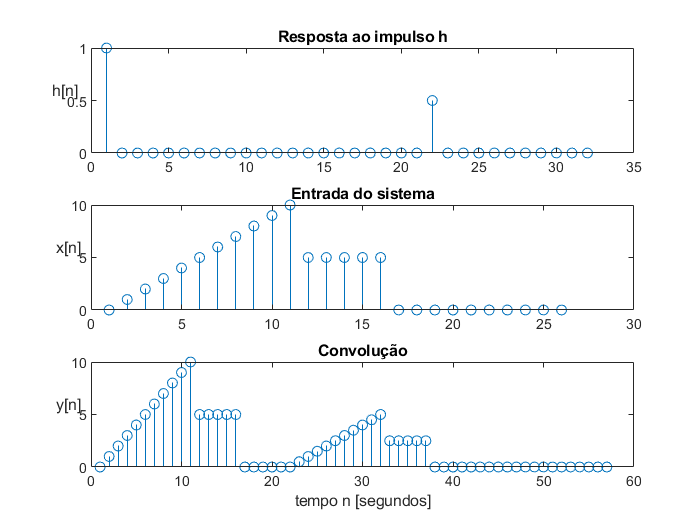

%figure(3);
subplot(3,1,3)
graph_y = stem(y);

title('Convolução')
xlabel('tempo n [segundos]') 
ylabel('y[n]', 'rotation', 0) 

#### Exercício 2: Convolução de um sinal sonoro

clear all; close all; clc;

Sinal puro

carregando o arquivo de áudio e o reproduzindo

load('trumpet.mat')   % salva o arquivo na variável y
sound(y,Fs)           % variável Fs da memória do Matlab
fprintf('Comprimento do vetor y: %i', size(y,1))

Comprimento do vetor y: 28000

plotando curva do sinal puro

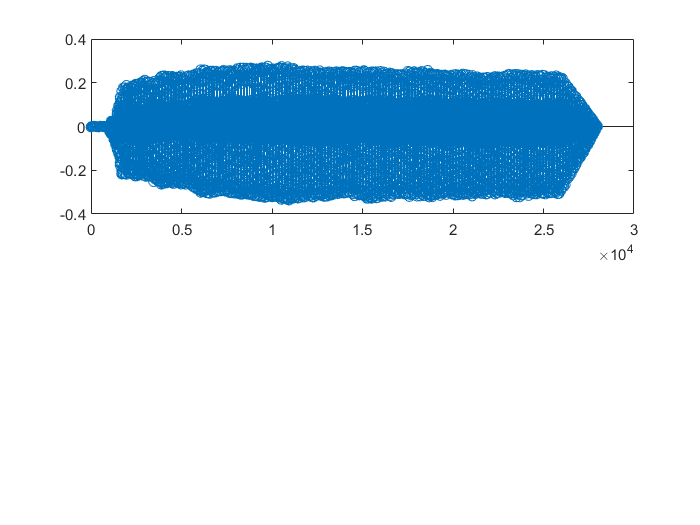

subplot(2,1,1);
graph_y = stem(y);

Convolução

realizando convolução 

h = [1 zeros(1,10000) 0.25 zeros(1,10000)];
fprintf('Comprimento do vetor h: %i', size(h,2))

Comprimento do vetor h: 20002


y1 = conv(y,h);
fprintf('Comprimento do vetor y1: %i', size(y1,1))

Comprimento do vetor y1: 48001

reproduzindo o aquivo de áudio

sound(y1,Fs)

plotando curva do sinal convolucionado

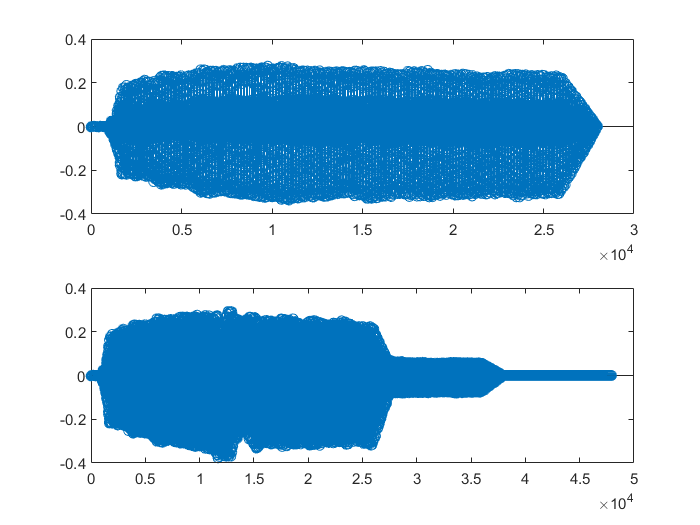

subplot(2,1,2);
graph_y1 = stem(y1);

#### Exercício 3: Resposta ao impulso quadrado

clear all; close all; clc;

lat e openheim 

videoaula openheim graph

(camisa laranja, gravatinha, bigodão)